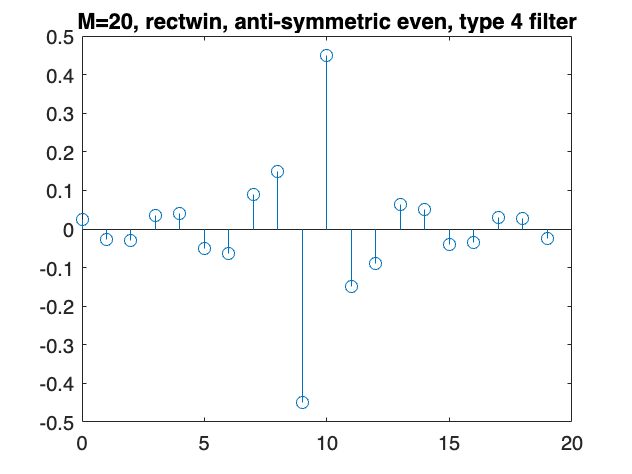

% HW 9

% Prob 1a, 1b, 1c
% Ideal LP h(n) is 1/(pi*n) * sin(n*wc)
% We can do frequency transformation by having
% h_hp(n) = (-1)^(n) h_lp(n), with cutoff frequency
% pi - wc. Since the desired high pass cutoff is 
% wc = pi/2, the wc of the low pass is also pi/2
% and the impulse response of h_hp(n) is 
% h_hp(n) = (-1)^(n) (k*sin(n*pi/2)/(pi*n)
% if length of filter is M, we need to shift the ideal
% response by (M-1)/2. Since we want high pass
% we cannot use Type 2 filter
figure;
M = 20;
hh = hamming(M)';
h_lp = ideal_lp(pi/2, M);
n = 0:1:length(h_lp)-1;
h_hp = (-1).^n .* h_lp;
stem(n, h_hp)
title('M=20, rectwin, anti-symmetric even, type 4 filter')

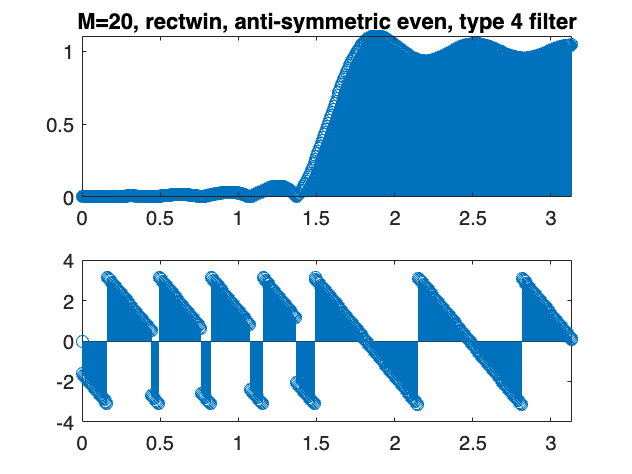


figure;
% using M = 20, it is a type 4 filter
[h,w]=freqz(h_hp, [1]);
subplot(2,1,1)
stem(w, abs(h))
title('M=20, rectwin, anti-symmetric even, type 4 filter')
subplot(2,1,2)
stem(w, angle(h))

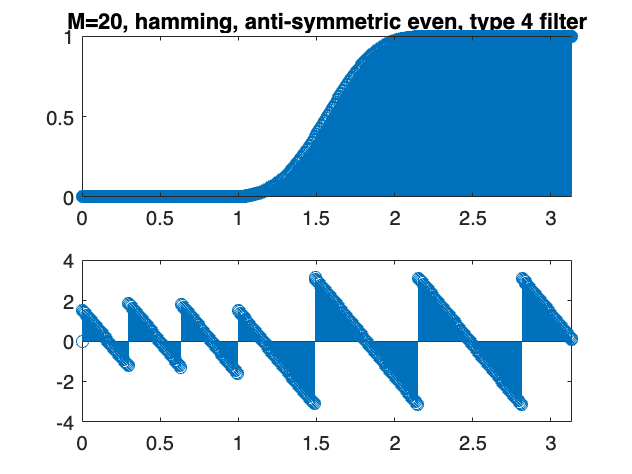


figure;
[h,w]=freqz(h_hp .* hh, [1]);
subplot(2,1,1)
stem(w, abs(h))
title('M=20, hamming, anti-symmetric even, type 4 filter')
subplot(2,1,2)
stem(w, angle(h))

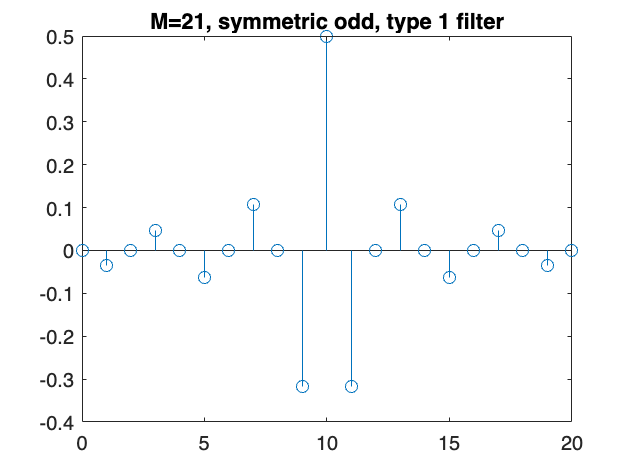



M = 21;
hh = hamming(M)';
h_lp = ideal_lp(pi/2, M);
n = 0:1:length(h_lp)-1;
h_hp = (-1).^n .* h_lp;
figure;
stem(n, h_hp)
title('M=21, symmetric odd, type 1 filter')

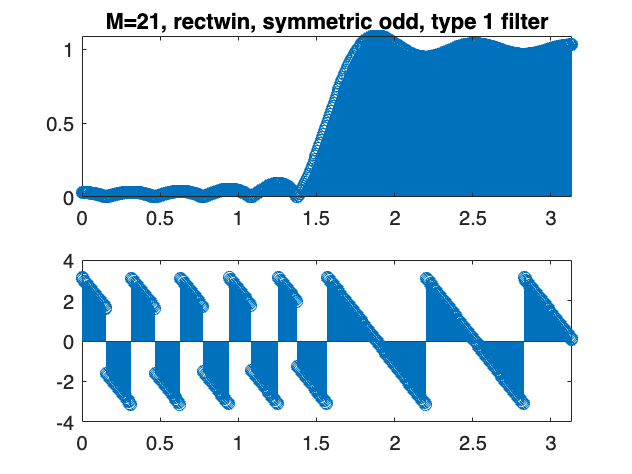

% using M = 21, it is a type 4 filter
[h,w]=freqz(h_hp, [1]);
subplot(2,1,1)
stem(w, abs(h))
title('M=21, rectwin, symmetric odd, type 1 filter')
subplot(2,1,2)
stem(w, angle(h))

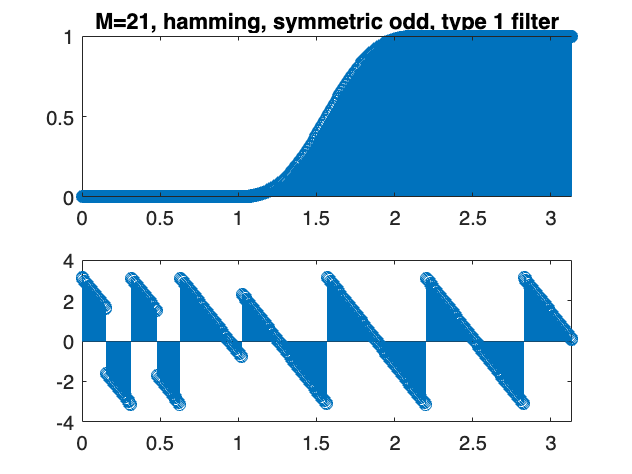


figure;
[h,w]=freqz(h_hp .* hh, [1]);
subplot(2,1,1)
stem(w, abs(h))
title('M=21, hamming, symmetric odd, type 1 filter')
subplot(2,1,2)
stem(w, angle(h))


% From the graphs we can see that type 1 and type 4
% filter types do not introduce visible difference
% However, using Hamming window smooths out the ripples
% the window type effect is more noticeable than the
% different types of impulse responses of approximate
% same length

% 1.d 
% for fs = 1000 Hz, pi == 500 Hz, the cutoff frequency
% is pi/2 which maps to 250 Hz.
% frequency resolution would be 1000/M
% We assume fs is 1000 Hz, as proposed in (d)
Fs = 1000;
Ts = 1/Fs;
t = 0:Ts:1;
cs = cos(2*pi*400 * t);
length(cs)

ans = 1001

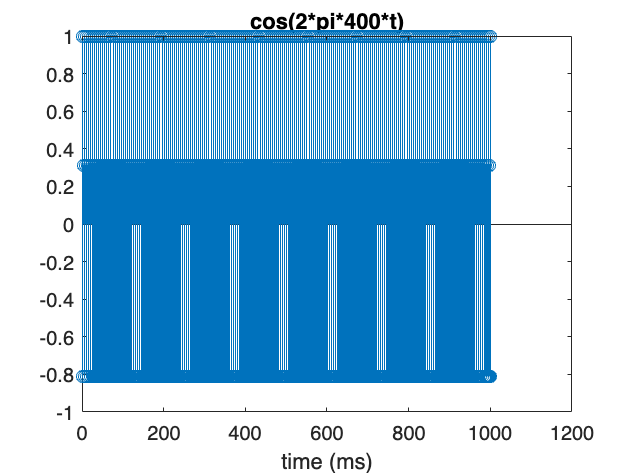

figure;
stem(cs)
title('cos(2*pi*400*t)');
xlabel('time (ms)')

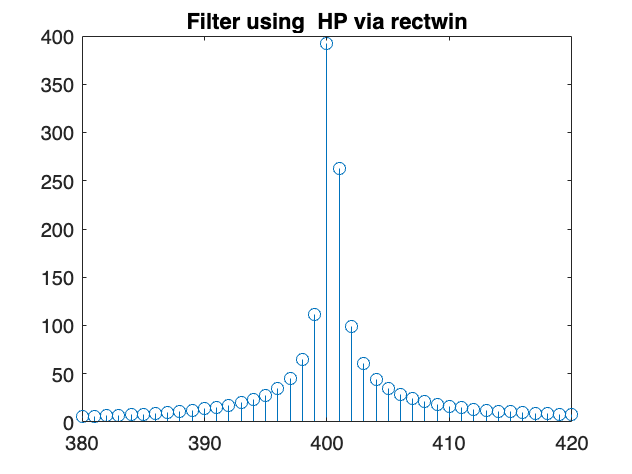

csfr = filter(h_hp, [1], cs);
csfh = filter((h_hp .* hh), [1], cs);
L = length(csfr);
f = -Fs/2:Fs/(L-1):Fs/2;
figure;
stem(f,abs(fftshift(fft(csfr))));
title('Filter using  HP via rectwin');
axis([380 420 0 400])

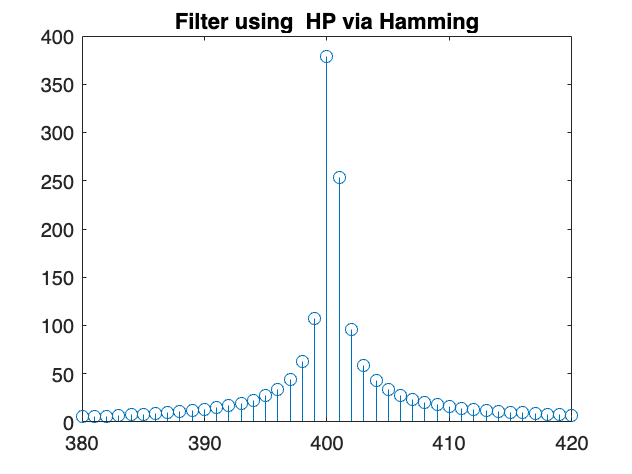

figure;
stem(f,abs(fftshift(fft(csfh))));
axis([380 420 0 400])
title('Filter using  HP via Hamming');

% No visible difference could be detected using
% rectangular window or hamming. The single
% frequency component could be seen clearly, and
% power was leaked to nearby frequencies but
% in similar manner

% Prob 2
%
% We can create bandpass filter responses from 
% ideal low pass responses.
% since fs = 1000 Hz, the band pass of 200 Hz is
% 2*pi/5, 250 is pi/2. If we need frequency 
% resolution of 20 Hz, we need to have 
% df = 1/(M*Ts), thus M = 1000/20 = 50;
M = 50;
fs = 0:10:490;
length(fs)

ans = 50

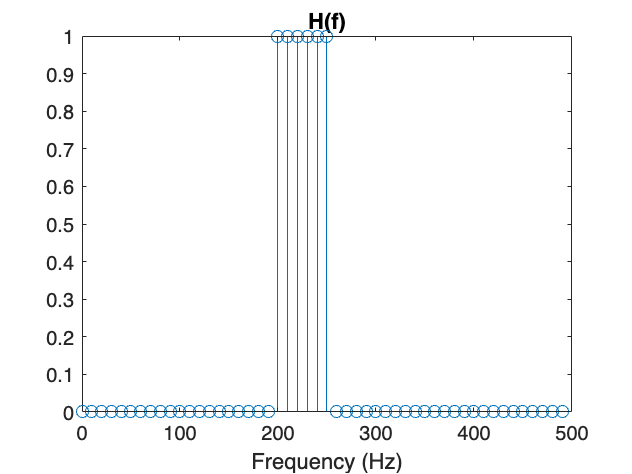

Hf = zeros(1,length(fs));
Hf(1,fs>= 200 & fs <= 250) = 1;
% 2a
figure;
stem(fs, Hf)
title('H(f)');
xlabel('Frequency (Hz)')

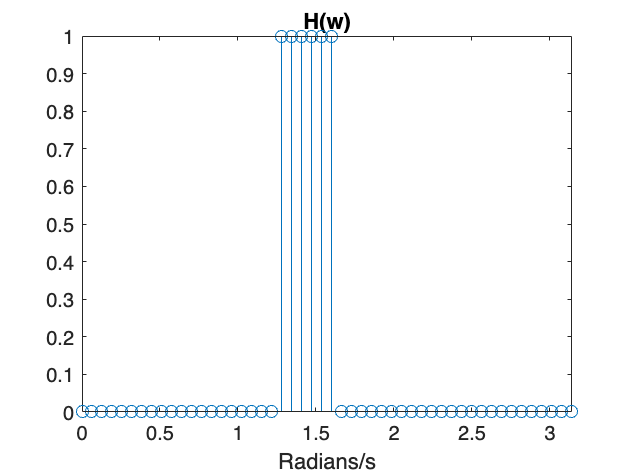

% 2b
figure;
ws = 0:pi/(M-1):pi;
stem(ws, Hf)
title('H(w)');
xlabel('Radians/s')

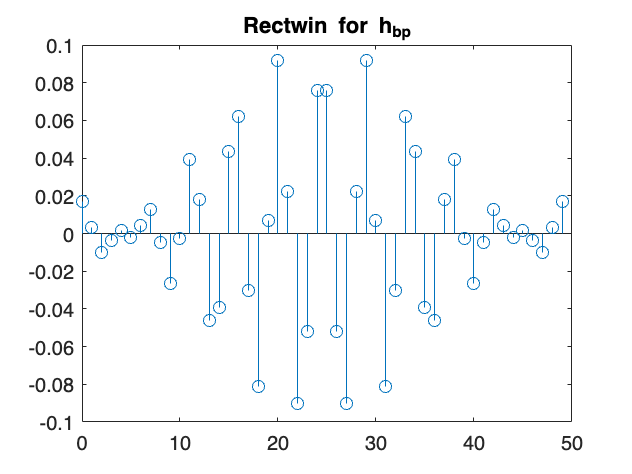

% 2c
wc2 = pi/2;
wc1 = 2*pi/5;
hh = hamming(M)';
hbp = ideal_lp(wc2,M) - ideal_lp(wc1,M);
figure;
stem(0:(M-1),hbp);
title('Rectwin for h_bp');

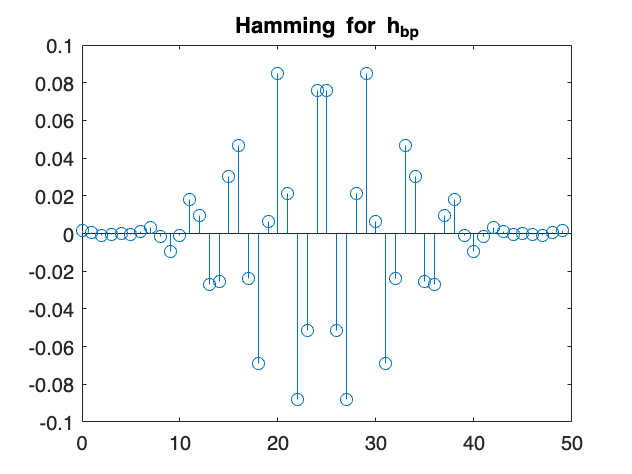

% 2d
figure;
stem(0:(M-1),hbp .* hh);
title('Hamming for h_bp');

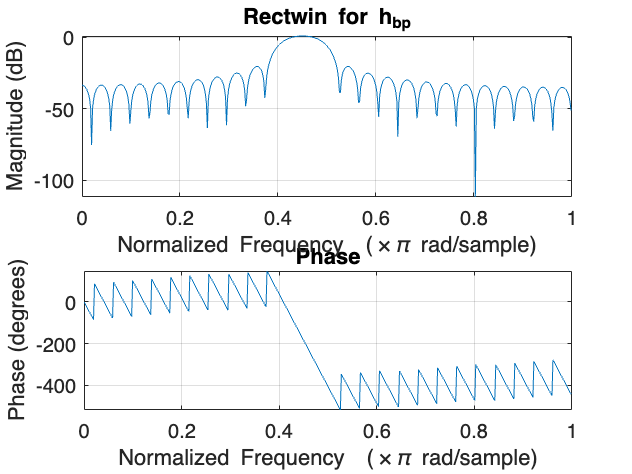

% 2e.c
freqz(hbp,[1])
title('Rectwin for h_bp');

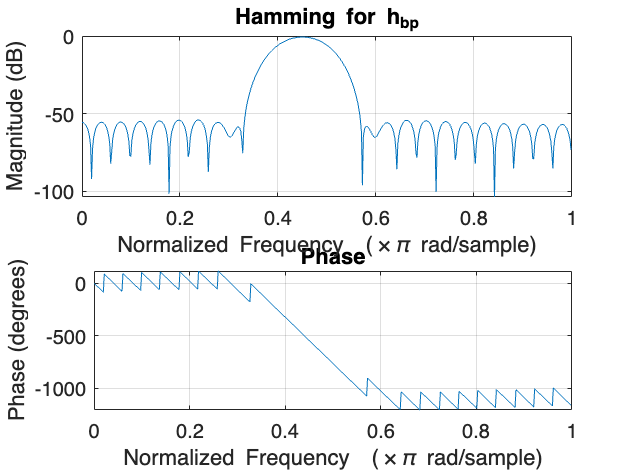

% 2e.d
freqz(hbp .* hh,[1])
title('Hamming for h_bp');

% Prob 3
As = 50;
Fs = 8000;
df = 500;
fc = 1500;
Rp = 1; % we set this to a small value
f = [ (fc - df/2) (fc + df/2) ];
ws = (fc + df/2)*2*pi/Fs;
a = [1 0];
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp))

d1 = 0.0575

d2 = db2mag(-As)*(1+d1)

d2 = 0.0033

d=[ d1 d2 ];

[M, fo, ao, W]=firpmord(f,a,d,Fs);
M 

M = 27

M = 33 % original suggestion of 27 does not attenuate enough

M = 33

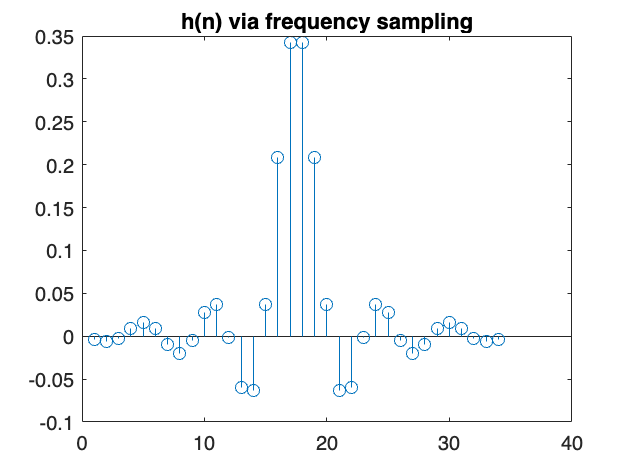

% 3a
h = firpm(M,fo, ao, W);
figure;
stem(h)
title('h(n) via frequency sampling')

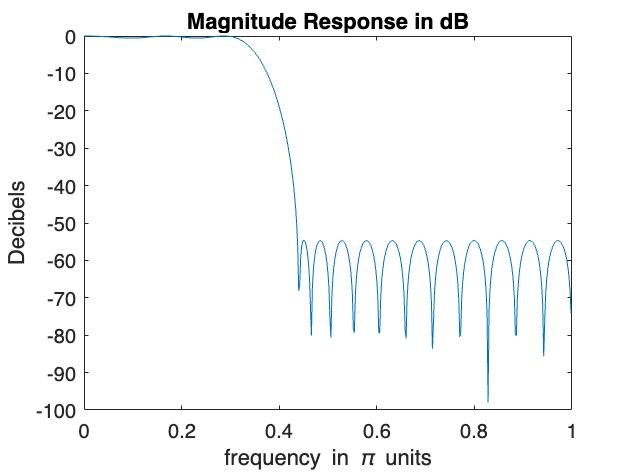

[db,mag,pha,grd,w] = freqz_m(h,[1]); 
delta_w = 2*pi/1000;
% 3b
figure;
plot(w/pi,db);title('Magnitude Response in dB');
xlabel('frequency in \pi units');
ylabel('Decibels')

% 3c
As = -round(max(db(floor(ws/delta_w+2):1:501))) % Min Stopband Attenuation

As = 55

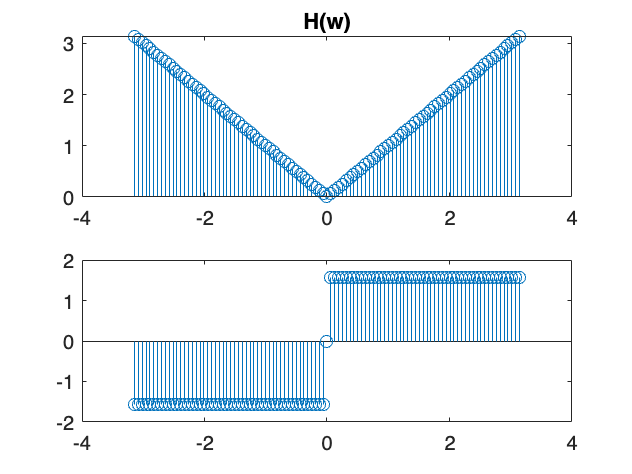

% Prob 4
w = -pi:2*pi/100:pi;
hd = j*w;
% 4a
figure;
subplot(2,1,1)
stem(w, abs(hd))
title('H(w)')
subplot(2,1,2);
stem(w,angle(hd))


% 4b (pdf)
% 4c
%function h = h_diff(P)
%% h = h_diff(P)
%% h is the non-causal FIR filter of length
%% N = 2*P + 1 which are the coefficients of
%% ideal differentiator

%n = -P:-1;
%h = (-1)^n ./ n;
%n = 1:P;
%h = [h 0 ((-1)^n ./ n)]
%end

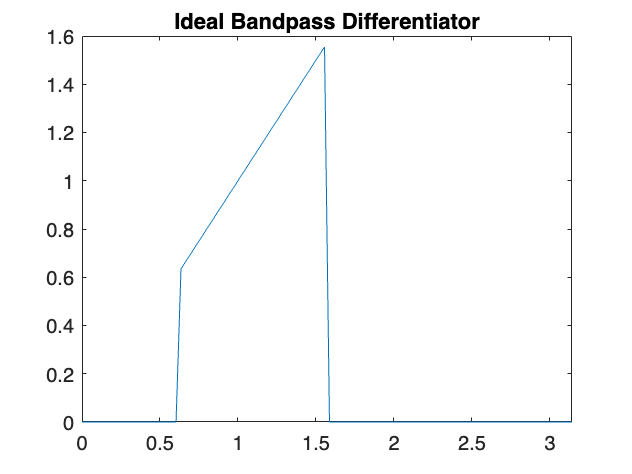

% Prob 5
clear all
Fs = 1000;
M = 100;
w = 0:pi/(M-1):pi;
hd = [];
% 5a
w1 = pi/5;
w2 = pi/2;

for i = 1:length(w)
    if w(i) >= w1 & w(i) <= w2
        h(1,i) = j*w(i);
    else
        h(1,i) = 0;
    end
end
figure
plot(w,abs(h))
title('Ideal Bandpass Differentiator');

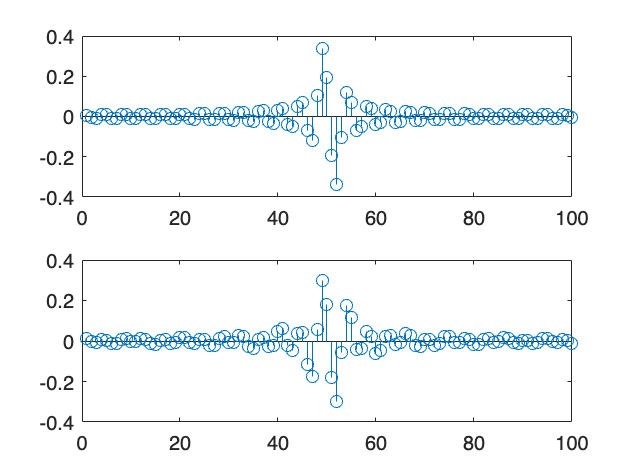

% 5b 
hh = kaiser(M,0.9);
hdlp = ideal_lp_diff(w2,M);
hbpdiff = ideal_lp_diff(w2,M) - ideal_lp_diff(w1,M);
figure;
subplot(2,1,1)
stem(hdlp)
subplot(2,1,2)
stem(hbpdiff);

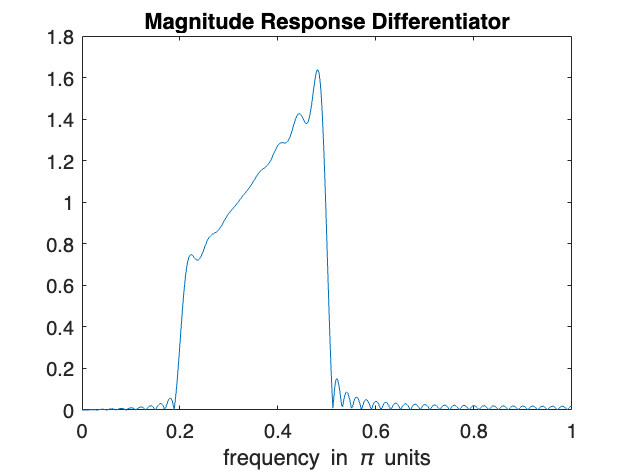

[db,mag,pha,grd,wfqzm] = freqz_m(hbpdiff,[1]); 
delta_w = 2*pi/1000;
% 5c
figure;
plot(wfqzm/pi,mag);title('Magnitude Response Differentiator');
xlabel('frequency in \pi units');

As = -round(max(db(floor(w2/delta_w+1):1:501))) % Min Stopband Attenuation

As = 5

% 5d
Rp = 0.1;
L = 50;
Fs = 1200;
wcs = 0.01:1/L:0.99;
fcs = (0.01:1/L:0.99)*600;
for i = 2:2:length(fcs)-2
    if wcs(i+1) < 1/5 | wcs(i) > 1/2
        a(i/2) = 0;
    else
        a(i/2) = (wcs(i) + wcs(i+1))/2;
    end
end
a = [0 a 0];
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp));
d2 = db2mag(-As)*(1+d1);
d = ones(1,length(a))*(d1);

[M, fo, ao, W]=firpmord(fcs,a,d,Fs);
M = 1100

M = 1100

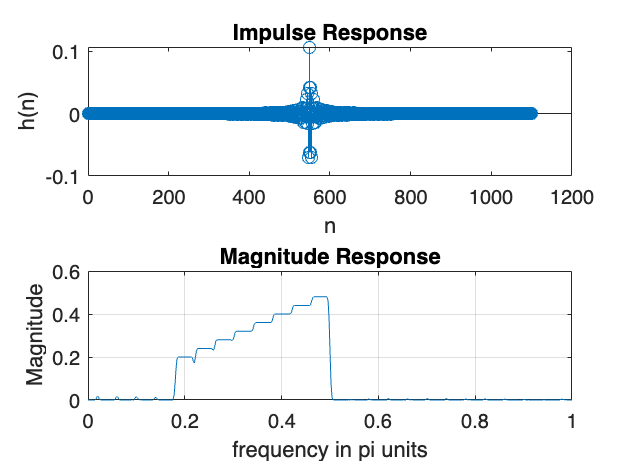

h = firpm(M,fo, ao, W);
n = 0:1:length(h)-1;
[db,mag,pha,grd,w] = freqz_m(h,[1]); 
delta_w = 2*pi/1000; 
wc2 = pi/2;
% Plots
figure;
subplot(2,1,1); stem(n,h);title('Impulse Response') 
%axis([0 N -0.1 0.3]);
xlabel('n'); ylabel('h(n)') 
subplot(2,1,2);plot(w/pi,mag);title('Magnitude Response');
grid; 
xlabel('frequency in pi units'); ylabel('Magnitude');

wc2 = pi/2 + pi/10;
As = -round(max(db(floor(wc2/delta_w+1):1:501))) % Min Stopband Attenuation

As = 38

function [db,mag,pha,grd,w] = freqz_m(b,a); 
% Modified version of freqz subroutine 
% ------------------------------------ 
% [db,mag,pha,grd,w] = freqz_m(b,a); 
% db = Relative magnitude in dB computed over 0 to pi radians 
% mag = absolute magnitude computed over 0 to pi radians 
% pha = Phase response in radians over 0 to pi radians 
% grd = Group delay over 0 to pi radians 
% w = 501 frequency samples between 0 to pi radians 
% b = numerator polynomial of H(z) (for FIR: b=h) 
% a = denominator polynomial of H(z) (for FIR: a=[1]) 
%
[H,w] = freqz(b,a,1000,'whole'); 
H = (H(1:1:501))'; w = (w(1:1:501))';
mag = abs(H); 
db = 20*log10((mag)/max(mag)); 
pha = angle(H); 
grd = grpdelay(b,a,w); 
end

function hd = ideal_lp(wc, M); 
% Ideal LowPass filter computation 
% -------------------------------- 
% [hd] = ideal_lp(wc,M) 
% hd = ideal impulse response between 0 to M-1 
% wc = cutoff frequency in radians 
% M = length of the ideal filter
%
L = (M-1)/2; n = [0:1:(M-1)]; 
m = n - L; fc2 = wc/pi; hd = fc2*sinc(fc2*m); 
end

function h = ideal_lp_diff(wc,M)
% h = diff_lp(wc, M)
% wc is the cutoff frequency
% M is the length of the filter
% h is the ideal response of the differentiator

L = (M-1)/2;
h = [];
for n=0:M-1
    m = n - L;
    if m == 0
        h(1,n+1) = 0;
    else
        h(1,n+1) = wc*cos(wc*m)/(pi*m) - sin(wc*m)/(pi*m^2);
    end
end
end